# Apuntes de Clase - Experimentos Aleatorios

Herramientas Matemáticas para el Manejo de la Información

Sesión 2 - 12 de febrero de 2026

## Características de un Experimento Aleatorio

- Existen al menos dos resultados posibles.

- Se conocen todos los resultados posibles.

- No se puede predecir el resultado.

- Observable.

- Repetible.

- Medible.

## Espacio Muestral

Es el conjunto de todos los resultados posibles de un experimento aleatorio.


$$S = \Omega$$


Ejemplos:

Lanzamiento de una moneda:


$$\Omega = \{\text{cara},\text{sello}\}$$


Lanzamiento de un dado:


$$\Omega = \{1,2,3,4,5,6\}$$


Selección de una carta de un maso de póquer:


$$\Omega = \{1,2,3,\dots,9,10,J,Q,K\} \times \{\text{corazones},\text{picas},\text{diamantes},\text{tréboles}\}$$


Puntos ganados por un equipo de fútbol al jugar un partido oficial:


$$\Omega =\{0,1,3\}$$


## Evento

Es un subconjunto del espacio muestral. En el caso de la moneda, los subconjuntos son:


$$A = \{\text{cara}\}$$



$$B = \{\text{sello}\}$$



$$C = \phi = \{\}$$



$$D = \{\text{cara},\text{sello}\}= \Omega$$


En el caso del lanzamiento del dado:


$$A = \{4\}$$



$$B = \{2,4,6\}$$



$$C = \{3,1,5\}$$



$$D = \{2,3,5\}$$



$$E = \{5,6\}$$



$$\vdots$$



$$\phi$$



$$\Omega$$


## Primer ejercicio

¿Cuáles son los eventos diferentes que se pueden formar en el experimento del partido de fútbol?

## Estudiantes que resolvieron correctamente el segundo ejercicio

Stiven Rodríguez

Angie Jiménez

Daniel Rodríguez

## Segundo ejercicio

¿Cuántos eventos diferentes se pueden formar en el experimento aleatorio del dado?

## Estudiante que resolvió correctamente el segundo ejercicio

Sergio Duarte

## Campo sigma - Sigma Álgebra

Una $\sigma - \text{álgebra} = \mathcal{F}$, sobre $\Omega$, es una colección de subconjuntos de $\Omega$ tal que:

- 
$$\Omega\in\mathcal{F}$$


- Si $A\in\mathcal{F}$; entonces, $A^c\in\mathcal{F}$ (cerrada bajo complemento).

- Si $A_1,A_2,A_3,\cdots\in\mathcal{F}$; entonces, $\bigcup_{n=1}^{\infty} A_n \in \mathcal{F}$ (cerrada bajo uniones numerables).

Nótese que el campo sigma más general es el conjunto potencia. Es tal caso, $\mathcal{F}$ sería el conjunto conformado por todos los subconjuntos diferentes de $\Omega$.

Para el lanzamiento de la moneda:


$$\mathcal{F} = \{\{\text{cara}\},\{\text{sello}\},\{\},\Omega\}$$



$$\vert \mathcal{F} \vert = 4$$


# Tarea 2

Explique con sus palabras, y con argumentos, la respuesta a la siguiente pregunta: ¿por qué el cardinal del campo sigma: $\mathcal F$, de un experimento aleatorio de $n$ resultados diferentes (con $n\in \mathbb Z^+$, $n\geq 2$), es $\vert \mathcal F \vert = 2^n$?

## Eventos Mutuamente Excluyentes

Dos eventos son mutuamente excluyentes si y solo si son disyuntos. 


$$A,B \subseteq \Omega$$



$$A\cap B = \{\} \Leftrightarrow A \text{ y } B\text{ son mutuamente excluyentes}$$


Por ejemplo, para el lanzamiento del dado:


$$B = \{2,4,6\}$$



$$C = \{3,1,5\}$$



$$H = \{1,2,3\}$$



$$B\cap C = \{ \} \Rightarrow B \text{ y } C \text{ son mutuamente excluyentes} $$



$$B\cap H = \{ 2\} \neq \{\} \Rightarrow B \text{ y } H \text{ no son mutuamente excluyentes} $$


## Partición del espacio muestral

Una partición del espacio muestral es la división en eventos mutuamente excluyentes, tales que la unión de ellos es $\Omega$.

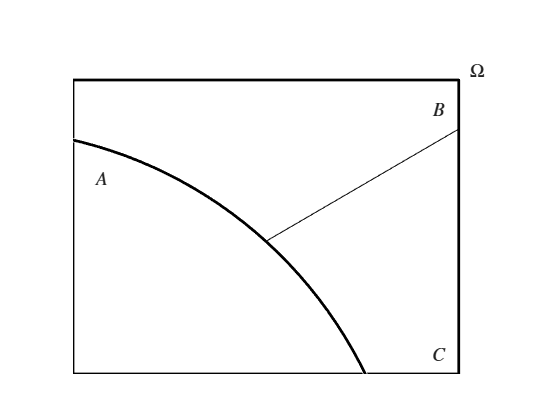

graficaparticion();

En el ejemplo:


$$\Omega=A\cup B\cup C$$



$$A \cap B = \{\}$$



$$A \cap C = \{\}$$



$$B \cap C = \{\}$$


# Axiomas de la Probabilidad

- Sea $A\subseteq \Omega$; entonces, $P[A] \geq 0$.

- Sean $A, B \subseteq \Omega \wedge A\cap B =\{\}$; entonces, $P[A\cup B] = P[A]+P[B]$.

- $P[\Omega] = 1$.

## Resultados interesantes (un par de propiedades)


$$\Omega = A \cup A^c$$



$$P[\Omega] = P[A \cup A^c]$$


En virtud de los dos últimos axiomas:


$$1= P[A]+P[A^c]$$


Entonces:


$$P[A^c]=1-P[A]$$


Adicionalmente, con $A=\Omega \Rightarrow A^c=\{\}$ y como $P[A^c]=1-P[A]$, se concluye que:


$$P[\{\}]=1-P[\Omega]$$



$$P[\{\}]=0$$


## Tercer ejercicio

Demuestre que si $A\subseteq \Omega$; entonces, $0\leq P[A] \leq 1$

## Estudiantes que resolvieron correctamente el ejercicio

Juan Rodríguez

Diego Soto

## Demostración

Por definición, el complemento de un subconjunto también pertenece al conjunto universal; entonces:


$$A^c \subseteq \Omega$$


El primer axioma asegura que:


$$P[A^c]\geq 0$$


y como se demostró previamente:


$$P[A^c]=1-P[A]$$


Por lo que se concluye que:


$$1-P[A] \geq 0$$


Esto es:


$$P[A]\leq 1$$


A su vez, considerando el primer axioma: $P[A] \geq 0$, se obtiene:


$$0\leq P[A] \leq 1$$


# Tarea 3

Demuestre que si $A,B \subseteq \Omega$; entonces, $P[A\cup B]=P[A] + P[B]-P[A\cap B]$. Utilice únicamente los axiomas de probabilidad y las propiedades demostradas en clase.

# Funciones locales

Esta función realiza la gráfica de la partición:

function [] = graficaparticion()
    plot([0,4,4,0,0],[0,0,3,3,0],'k','linewidth',2);
    hold on;
    viscircles([-1,-2],4.5,'Color','k');
    plot([2,4],[sqrt(45)/2-2,2.5],'k');
    hold off;
    axis([0,4.5,0,3.5]);
    text(4.1,3.1,'$\Omega$','FontSize',14,'Interpreter','latex');
    text(0.2,2,'$A$','FontSize',14,'Interpreter','latex');
    text(3.7,2.7,'$B$','FontSize',14,'Interpreter','latex');
    text(3.7,0.2,'$C$','FontSize',14,'Interpreter','latex');
    axis off;
end